outputdir = "D:\\Whale Data\\Raw Audio Data\\";
inputdirs = [...
    "D:\\Whale Data\\POIData\\1",...
    "D:\\Whale Data\\POIData\\2",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\MaudRise2014\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\RossSea2014\\wav",...
    ];

outputnames = [...
    "FalseBay2022Aug",...
    "FalseBay2022Oct",...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    "MaudRise2014",... %weird format thing??
    "RossSea2014",...
    ];

dtformats = [...
    "yyyyMMdd_HHmmss_SSSS",...
    "yyyyMMdd_HHmmss_SSSS",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    ];

fs = [...
    2000,...
    2000,...
    1000,...
    1000,...
    1000,...
    1000,...
    1000,...
    ];

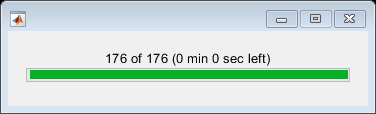

Worker 3: 
Worker 4: 
Worker 3: 
  > In audiowrite>clipInputData (line 474)
  In audiowrite (line 245)
  In 

for i = 1:numel(outputnames)
    targetdir = outputdir + outputnames(i);
    adc = AudioDataConverter(inputdirs(i), targetdir, dtformats(i), fs(i));
    adc.convert();
end

sfbFreq = {...
    [25, 1000],...
    [25, 1000],...
    [10, 500],...
    [10, 500],...
    [10, 500],...
    [10, 500],...
    [10, 500],...
    };

for i = 1:2
    sc = SpectrogramCreator(outputnames(i));
    f = sfbFreq{i};
    sc.create(16, 0.05, fs(i), AudioDataConverter.L, f(1), f(2));
end

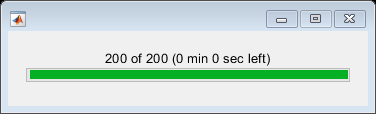

Worker 3: 
Worker 4: 
Worker 3: 
  > In audiowrite>clipInputData (line 474)
  In audiowrite (line 245)
  In 

adc = AudioDataConverter("D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\MaudRise2014\\wav", outputdir + "MaudRise2014", dtformat, 1000);
adc.convert();

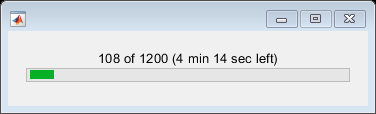

sc = SpectrogramCreator("MaudRise2014");
sc.create(16, 0.05, 1000, AudioDataConverter.L, 10, 500);

inputdirs = [...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\",
    ];

outputdir = "D:\\Whale Data\\Raw Audio Data\\";
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",
    ];

dtformat = "yyyyMMdd_HHmmss";

for fidx = 1:numel(inputdirs)

    pathformatted = outputdir + outputnames(fidx);
    pathorig = inputdirs(fidx) 

    dl = DataLoader2(pathformatted, 'wav', 'single', true);
    filelist = dl.filelist;
    FIDlist = [filelist.fid];
    [filelisttimes, sidx] = sort([filelist.time]);
    filelist = filelist(sidx);
    FIDlist = FIDlist(sidx);

    files = dir(pathorig);
    annotations = convertCharsToStrings({files.name});
    idx = arrayfun(@(s) s.contains("selections.txt"), annotations);
    annotations = annotations(idx)
    ann = {};
    for fname = annotations
        T = readtable(pathorig + fname, "Delimiter","\t");
        idx = find(fname{:} == '.');
        type = extractBetween(fname, idx(1)+1, idx(end-1)-1);
        type = type.replace(".", "_");
        type = repmat(type, size(T, 1), 1);
        T(:, 'Type') = cellstr(type);
        ann{end + 1} = T;
    end
    masterTable = {};
    for T = ann
        T = T{:};
        row = table();
        row.File = convertCharsToStrings(T.BeginFile);
        if ~isempty(row)


            row.StartIdx = T.BegFileSamp_samples_;
            row.EndIdx = T.EndFileSamp_samples_;
            row.Duration = T.DeltaTime_s_;
            row.StartFrequency = T.LowFreq_Hz_;
            row.EndFrequency = T.HighFreq_Hz_;
            row.Annotation = convertCharsToStrings(T.Type);

            %match the correct file
            timestr = extractBefore(lower(row.File), ".wav");
            timestr = extractBetween(timestr, 1, strlength(dtformat));
            ftime = datetime(timestr, "InputFormat", dtformat);
            dt = seconds(row.StartIdx/1000);
            ftime = ftime + dt;
            matchedfileidx = arrayfun(@(time)find(time >= (filelisttimes'), 1, "last"), ftime);
            matchedfile = [filelist(matchedfileidx).name]';
            matchedfiletimes = [filelist(matchedfileidx).time]';
            matchedfids = [FIDlist(matchedfileidx)]';
            offset = floor(seconds(ftime - matchedfiletimes)*1000);
            dur = ceil(row.Duration * 1000);
            row.StartIdx = offset;
            row.EndIdx = row.StartIdx + dur;
            row.OrigFile = row.File;
            row.File = matchedfile;
            row.FileID = matchedfids;
            

            masterTable{end + 1} = row;
        end
    end
    masterTable = vertcat(masterTable{:});
    masterTable.AnnotationID = (1:size(masterTable, 1))';
    annotationTable = masterTable(masterTable.Annotation ~= "Unidentified_calls" & masterTable.Annotation ~= "unid", :);
    unidentifiedTable = masterTable(masterTable.Annotation == "Unidentified_calls" | masterTable.Annotation == "unid", :);
    savepath = pathformatted + "\\annotations";
    mkdir(savepath);
    save(savepath + "\\annotations.mat", "masterTable", '-mat');
end

pathorig = "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\"

annotations = 1×11 string array
    "Balleny2015.BmAnt-A.selections.txt"    "Balleny2015.BmAnt-B.selections.txt"    "Balleny2015.BmAnt-Z.selections.txt"    "Balleny2015.BmD.selections.txt"    "Balleny2015.Bp20Hz.selections.txt"    "Balleny2015.Bp20Plus.selections.txt"    "Balleny2015.BpDwnswp.selections.txt"    "Balleny2015.BpHigherCall.selections.txt"    "Balleny2015.humpback.selections.txt"    "Balleny2015.minke.selections.txt"    "Balleny2015.unid.selections.txt"


pathorig = "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\"

annotations = 1×8 string array
    "Casey2017.Bm.Ant-A.selections.txt"    "Casey2017.Bm.Ant-B.selections.txt"    "Casey2017.Bm.Ant-Z.selections.txt"    "Casey2017.Bm.D.selections.txt"    "Casey2017.Bp.20Hz.selections.txt"    "Casey2017.Bp.20Plus.selections.txt"    "Casey2017.Bp.Downsweep.selections.txt"    "Casey2017.Unidentified.calls.selections.txt"


pathorig = "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\"

annotations = 1×9 string array
    "Kerguelen2015.Bm.Ant-A.selections.txt"    "Kerguelen2015.Bm.Ant-B.selections.txt"    "Kerguelen2015.Bm.Ant-Z.selections.txt"    "Kerguelen2015.Bm.D.selections.txt"    "Kerguelen2015.Fin.20Hz.selections.txt"    "Kerguelen2015.Fin.20Plus.selections.txt"    "Kerguelen2015.Fin.DS.selections.txt"    "Kerguelen2015.MinkeDS.selections.txt"    "Kerguelen2015.Unidentified.calls.selections.txt"


outputdir = "D:\\Whale Data\\Raw Audio Data\\";
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];


for fidx = 1:numel(outputnames)

    pathformatted = outputdir + outputnames(fidx);
    spectropath = pathformatted + "\\spectrograms\\";
    annpath = pathformatted + "\\annotations\\";
    annotationTable = load(annpath + "annotations.mat").masterTable;
    load(spectropath + "filterbank.mat")

    threadidx = ThreadIdx(size(annotationTable, 1), 6);

    fbfs = fb.getSSamplingFreq();
    spmd %for i = 1
        counter = 1;
        while ~threadidx.complete(spmdIndex)
            try
            idx = threadidx.next(spmdIndex);
            row = annotationTable(idx, :);
            name = extractBefore(row.File, ".wav");
            spectroname = name + ".mat";        
            s = load(spectropath + spectroname).s;
            s = s.^2;
            logs = log(s);
            fig = figure("Visible", "off");
            fb.plotS(s, true);
            t = [row.StartIdx, row.EndIdx]/1000;
            tlims = [max(row.StartIdx-500, 0), min(row.EndIdx+500, AudioDataConverter.L)]/1000;
            fbox = [row.StartFrequency, row.StartFrequency, row.EndFrequency, row.EndFrequency];
            tbox = [t(1), t(2), t(2), t(1)];
            xlim(tlims);
            clim([min(logs, [],"all"), max(logs, [],"all")])
            hold on
            fill( tbox, fbox, 'r', "FaceAlpha",0.1, "EdgeAlpha",0.8);
            hold off
            fname = sprintf("%s (%s) (%d)", row.Annotation, extractBefore(row.File, ".wav"), counter);
            title(fname, "Interpreter","none");
            saveas(fig, annpath + fname + ".png")
            close(fig);
            counter = counter + 1;
            catch e
                disp(getReport(e, "extended"))
            end
        end        
    end
    
end

%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

for idx = 1:numel(outputnames)
    sc = SpectrogramCreator(outputnames(idx));
    sc.create(16, 0.05, 1000, AudioDataConverter.L, 10, 500);
end

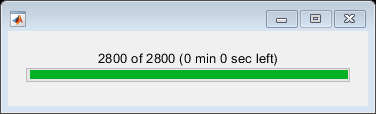

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to the parallel pool (number of workers: 6).


%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

for idx = 1:numel(outputnames)
    gc = SEGMMCreator(outputnames(idx), 62.5);
    gc.create();
end

%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

for idx = 1:numel(outputnames)
    cc = ContourCreator(outputnames(idx));
    cc.create();
end

%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

for idx = 1:numel(outputnames)
    cl(idx) = ContourLabeler(outputnames(idx), 62.5, 1000);
    cl(idx).match();
end

   19.9601

   39.9202

   59.8802

   79.8403

   99.8004

    8.8652

   17.7305

   26.5957

   35.4610

   44.3262

   53.1915

   62.0567

   70.9220

   79.7872

   88.6525

   97.5177

    5.9032

   11.8064

   17.7096

   23.6128

   29.5159

   35.4191

   41.3223

   47.2255

   53.1287

   59.0319

   64.9351

   70.8383

   76.7414

   82.6446

   88.5478

   94.4510



for idx = 1:numel(outputnames)
    disp "------------------------"
    disp (outputnames(idx))
    ann = groupcounts(cl(idx).annotationTable, "Annotation");
    Annotation = "Unmatched";
    GroupCount = 0;
    Percent = 0;
    ann = [ann; table(Annotation, GroupCount, Percent)];
    det = groupcounts(cl(idx).contourTable, "Annotation");
    J = join(det, ann, "Keys", "Annotation");
    J.PercentDetected = J.GroupCount_det./J.GroupCount_ann*100;
    J(:, ["Annotation", "PercentDetected", "GroupCount_ann", "GroupCount_det"])
end

"------------------------"


BallenyIslands2015


ans = 12×4 table
      Annotation      PercentDetected    GroupCount_ann    GroupCount_det
    ______________    _______________    ______________    ______________

    "BmAnt-A"             105.09              923                970     
    "BmAnt-B"             138.64               44                 61     
    "BmAnt-Z"             261.29               31                 81     
    "BmD"                    100               47                 47     
    "Bp20Hz"               58.78              951                559     
    "Bp20Plus"            197.97              148                293     
    "BpDwnswp"            60.256               78                 47     
    "BpHigherCall"        91.329              173                158     
    "Unmatched"              Inf                0              28895     
    "humpback"               435

"------------------------"


CaseyIslands2017


ans = 8×4 table
         Annotation         PercentDetected    GroupCount_ann    GroupCount_det
    ____________________    _______________    ______________    ______________

    "Bm_Ant-A"                  117.92              1741              2053     
    "Bm_Ant-B"                  139.78               558               780     
    "Bm_Ant-Z"                  170.59               119               203     
    "Bm_D"                      83.183               553               460     
    "Bp_20Hz"                   19.231                78                15     
    "Bp_20Plus"                 59.346               214               127     
    "Unidentified_calls"        203.85               130               265     
    "Unmatched"                    Inf                 0             61389     


"------------------------"


KerguelenIslands2015


ans = 10×4 table
         Annotation         PercentDetected    GroupCount_ann    GroupCount_det
    ____________________    _______________    ______________    ______________

    "Bm_Ant-A"                   100.2              1970              1974     
    "Bm_Ant-B"                  127.12               542               689     
    "Bm_Ant-Z"                  231.78               236               547     
    "Bm_D"                      62.458              1180               737     
    "Fin_20Hz"                  63.406               552               350     
    "Fin_20Plus"                99.025               718               711     
    "Fin_DS"                    2.0349               344                 7     
    "MinkeDS"                   243.73               773              1884     
    "Unidentified_calls"        180.95        